# Nelder-Mead 算法

下山纯形法

[Nelder-Mead 算法](http://www.scholarpedia.org/article/Nelder-Mead_algorithm)(原文链接)是一种求多元函数局部最小值的直接搜索算法，其优点是不需要函数可导并能较快收敛到局部最小值．

solve the classical unconstrained optimization problem of minimizing a given nonlinear function $f:R^{n\;} \to R$

- uses only ***function values*** at some points in $R^{n\;}$

- ***never*** try to form ***an approximate gradient*** at any of these points.

## 纯形 Simplex

In [geometry](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Geometry), a **simplex **is a generalization of the notion of a [triangle](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Triangle) or [tetrahedron](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Tetrahedron) to arbitrary [dimensions](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Dimensions).

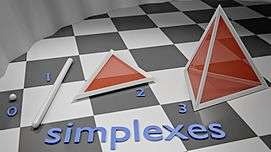

a 0-simplex is a point,

a 1-simplex is a [line segment](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Line_segment),

a 2-simplex is a [triangle](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Triangle),

a 3-simplex is a [tetrahedron](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Tetrahedron),

a 4-simplex is a [5-cell](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/5-cell).

### 定义

a ***k*****-simplex** is a *k*-dimensional [polytope](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Polytope) which is the [convex hull](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Convex_hull) of its *k* + 1 [vertices](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Vertex_(geometry)).

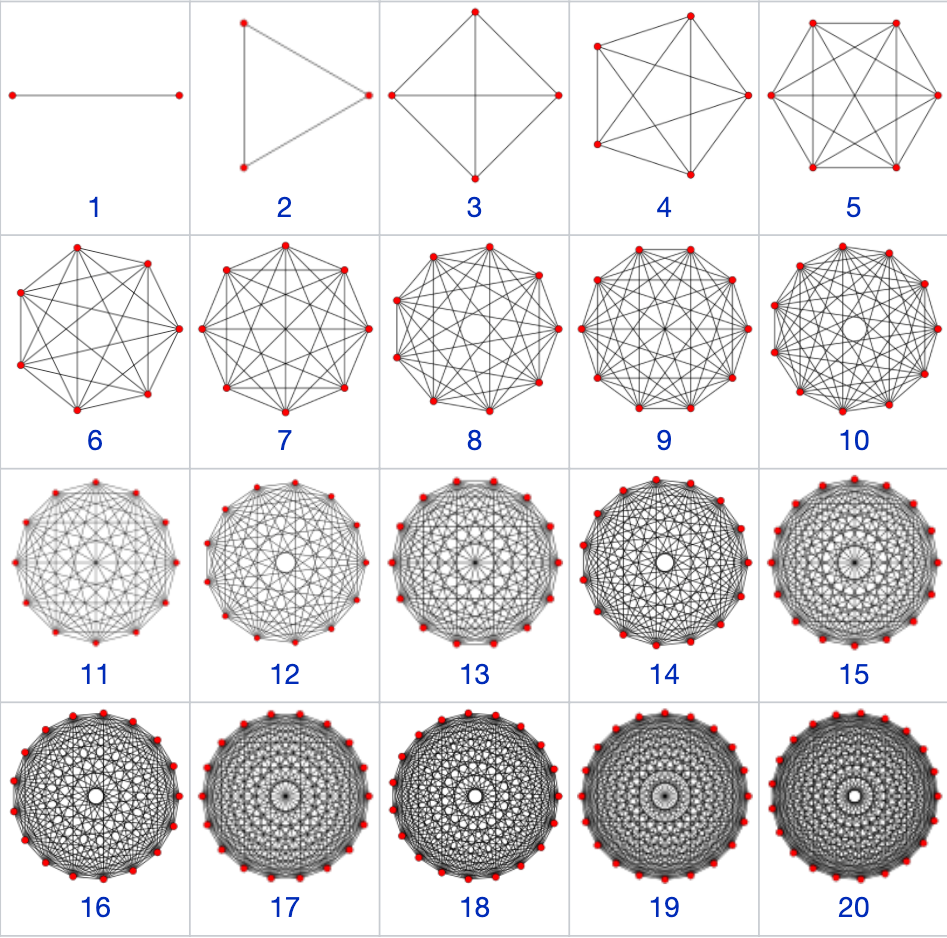

## 前奏 

recommand([Direct search methods:then and now](https://doi.org/10.1016/S0377-0427(00)00423-4))

### Direct Search /Derivative-Free Search/Black-Box Search/*Pattern search (optimization)*

- ***Hooke, R.; Jeeves, T.A. (1961). ****""Direct search" solution of numerical and statistical problems". Journal of the ACM. ****8**** (2): 212–229. doi:*[*10.1145/321062.321069*](https://doi.org/10.1145%2F321062.321069)*.*

*恩里科·费尔米和尼古拉斯·梅求坡里斯第一台数字计算机Los Alamos Maniac来确定特定理论参数（相位移）哪些值最符合实验数据（散射交叉部分）。他们每次已同样的步长变化一个理论参数，当这些任意的参数的增加和减少不能再改进符合实验数据时，他们就将步长变为原来的一半继续这样的过程直到认为步长足够小。他们的简单方法虽然慢但确是正确的。*

*They varied one theoretical parameter at a time by steps of the same magnitude, and when no such increase or decrease in any one parameter further improved the fit to the experimental data, they halved the step size and repeated the process until the steps were deemed sufficiently small.Their simple procedure was slow but sure,……*

$--$ Davidon

### 单纯性法

- ***Spendley, W.; Hext, G. R.; Himsworth, F. R. (1962).**** "Sequential Application of Simplex Designs in Optimisation and Evolutionary Operation". Technometrics. ****4**** (4): 441–461. doi:*[*10.1080/00401706.1962.10490033*](https://doi.org/10.1080%2F00401706.1962.10490033)*.*

***first ****simplex-based direct search method *

早期的直接搜索法在任何地方都需要2n到2n个目标估值完成叠代改进的进行搜索；Spendley 他们证明不需要n+1个以上的目标函数的值来确定上升（或下降）方向；

也就是说：只要n+1个f(x)图像中的点就可确定一个平面，利用n+1个f(x)值的有限差分估计。同时，n+1个点确定一个单纯形。

这引出了单纯形搜索的基本思想：在$R^n$空间中构造一个**非退化单纯形**并用单纯形驱动搜索。

-  **A nondegenerate simplex **is one for which the set of edges adjacent to any vertex in the simplex forms a basis for the space.

- 一个非退化的单纯形是与任意顶点相连的边集组成空间的基(通过与给定点相连的边的线性组合来构造域中任意点的搜索)

如果用某个点的相对于其象对面中心的对称点代替该点后仍然是单纯形。

                     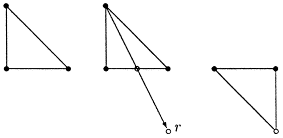

1.镜像变换

    在单纯形中确定“最差”顶点（例如：最小期望目标值的；然后通过向对面映射最差单纯形。

    如果映射后的点仍然是最差的，则选择“次差”顶点继续这个过程。

   收尾条件: 算法一直在通过相对面的中心翻转顶点来移动单纯形（而不是最好顶点）。

- 最优解的候选: 当一个**镜像顶点**引起**最优顶点**的**目标值单调减**时，我们就有了一个最优解的新的候选

- 最优解的确定: 单纯形的循环序列

          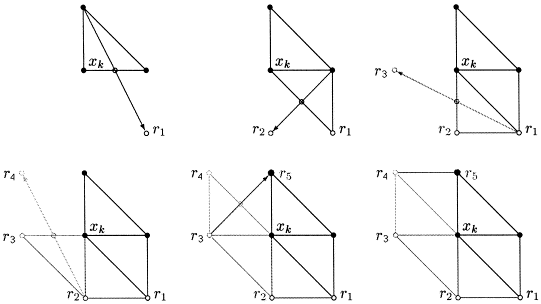

               ** 一个映射的序列，都没有成功取代最好顶点，而回到了这个序列开始的单纯形。**

2 收缩

    在 1、2 维情况时 ，会出现这种返祖现象，我们可以采取 减少连到最好顶点的边长（或者其他办法）

### 起源

- For Nelder, the starting point was a 1963 conference talk by William Spendley of Imperial Chemical Industries about a “simplex” method recently proposed by Spendley, Hext, and Himsworth for response surface exploration.

- Inspired by Spendley’s talk, Nelder had what he describes as “one useful new idea”: while defining each iteration via a simplex, add the crucial ingredient that the shape of the simplex should “adapt itself to the local landscape”

- During a sequence of lively discussions with his colleague Roger Mead

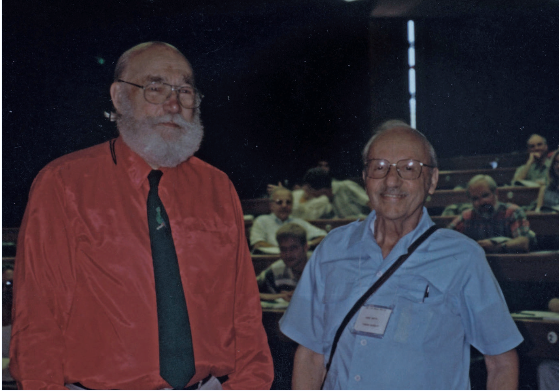			

John Nelder and George Dantzig, Stanford University, 1997, photographed by Margaret Wright

## 基本思想

Nelder-Mead 将单纯形搜索转变成可加快搜索的附加移动的优化算法

### ～初试纯形构造

The initial simplex **S** is usually constructed by generating n+1 vertices $x_0 ,\ldotp \ldotp \ldotp ,x_n$ around a given input point $x_{\textrm{in}} \in R^n$.

In practice, the most frequent choice is $x_0 =x_{\textrm{in}}$to allow proper restarts of the algorithm. 

The remaining n vertices are then generated to obtain one of two standard shapes of S:

- S is right-angled at x0 , based on coordinate axes, or $x_{j}:=x_{0}+h_{j} e_{j}, \quad j=1, \ldots, n$ where$h_j$ is a stepsize in the direction of unit vector $e_j$ in $R^n$.

- S is a regular simplex, where all edges have the same specified length.

### ～一步迭代

Nelder-Mead方法的一个迭代包括以下三个步骤。

#### **    1. 排序**：确定索引h,s,l为当前纯形相对的*最差*，*倒数第二*和*最好的*顶点：


$$f_h =\max_j f_j ,f_s =\max_{j\not= h} f_j ,f_l =\min_{j\not= h} f_j \ldotp$$


        或者直接函数值排序（ Lagarias et al. (1998)）：


$$f_0 \le f_1 \le \cdots \le f_{n-1} \le f_n ,\textrm{Then}\;l=0,s=n-1,\textrm{and}\;h=n$$


#### **    2. 质心**：计算*质心* c所述的*最好的*侧面（*最差的*顶点 $x_{h\;}$相反）


$$c:=\frac{1}{n}∑_{j\not= h} x_j \ldotp$$


#### **    3. 转换**：从当前的纯形计算新的纯形。

- 尝试仅通过使用相对于最佳方面的反射，扩展或收缩来变换*最差的*顶点$x_{h\;}$。所有测试点都位于由$x_{h\;}$ 和 $c$的直线上

- 如果成功，则*接受*点将成为新单纯形的新顶点。

- 如果失败，则将单纯形向缩*最佳*顶点缩小 。 在这种情况下，重新计算n个边

### ～变换方法

Simplex transformations in the Nelder-Mead method are controlled by four parameters：


$$\alpha -\textrm{reflection},\beta -\textrm{contration},\rho -\textrm{expansion},\delta -\textrm{shrinkage}$$


一般地


$$\alpha>0, \quad 0<\beta<1, \quad \gamma>1, \quad \gamma>\alpha, \quad 0<\delta<1$$


常用地


$$\alpha=1, \beta=\frac{1}{2}, \gamma=2, \delta=\frac{1}{2}$$


#### 镜像：

Compute the *reflection* point $x_r :=c+\alpha \left(c-x_h \right)$ and $f_r :=f\left(x_r \right)$ . If $f_l \le f_r <f_s$ , accept $x_r$ and terminate the iteration.

x_r = c + alpha*(c-x_h);
if f(x_l)<= f(x_r) && f(x_r)<f(x_s)
    x(x_h_label) = [];
    x(end) = x_r;
    % sort
    x = sort(x);
    x_h = x(1);
    x_l = x(2);
    x_s = x(end);
    c = centroid(x);% We can use a class way
else
    % expand or contract
end

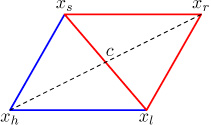

#### 拓展：

If $f_r <f_l$ , compute the *expansion* point $x_e :=c+\gamma \left(x_r -c\right)$ and$f_e :=f\left(x_e \right)$. If $f_e <f_r$ , accept$\;x_e$ and terminate the iteration.

 Otherwise (If $f_e >f_r$), accept $x_r$ and terminate the iteration.*----“****greedy minimization****” approach *

***NOTE****: The original Nelder-Mead paper uses “****greedy expansion****”, where *$x_e$* is accepted if *$f_e <f_r$* and f*$f_r <f_l$*, regardless of the relationship between *$f_r$* and *$f_e$* .* ***Sometimes useful for non-smooth functions****(* *for example, Rowan, 1990)*

if f(x_r)< f(x_l)
    x_e = c + gamma*(x_r - c);
    if f(x_e) < f(x_r)
        x = x.accept(x_e);
    else
        x = x.accept(x_r);
    end
else
    
end

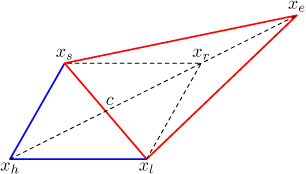

#### 缩并：

If $f_r \ge f_s$  , compute the *contraction* point $x_c$ by using the better of the two points $x_h$ and $x_r$ .

**Outside**: If $f_s \le f_r <f_h$ , compute $x_c :=c+\beta \left(x_r -c\right)$ and $f_c :=f\left(x_c \right)$ . If $f_c \le f_r$ , accept $x_c$ and terminate the iteration.

Otherwise, perform a shrink transformation.

**Inside**: If${\;f}_r \ge f_h$ , compute $x_c :=c+\beta \left(x_h -c\right)$ and $f_c :=f\left(x_c \right)$ . If $f_c \le f_h$ , accept $x_c$ and terminate the iteration.

Otherwise, perform a shrink transformation.

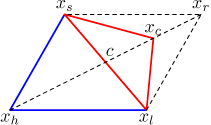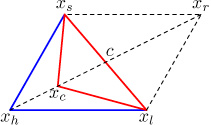

if f(x_r)>= f(x_s)
    if f(x_r) < f(x_h)
        x_c = c + beta*(x_r - c);
        f_compare = f(x_c);
    else
        x_c = c + beta*(x_h - c);
        f_compare = f(x_h);
    end
    if f(x_c) < f_compare
        x = x.accept(x_c);
    else
        %shrink
    end
end

#### 收缩：

Compute n new vertices: $x_j :=x_l +\delta \left(x_j -x_l \right)$and $f_j$

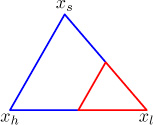

*A failed contraction is much rarer, but can occur ****when a valley is curved and one point of the simplex is much farther from the valley bottom than the other****s; contraction may then cause the reflected point to move away from the valley bottom instead of towards it. Further contractions are then useless. The action proposed contracts the simplex towards the lowest point, and will eventually bring all points into the valley.*

x = x.gen(x_l,delta);

～收敛判断

- x  (simplex small)

- f （when all values close enough）

- 失败 (num > max_iter)

### 相关问题

#### 效率

在使用Nelder-Mead方法进行了许多年的数值经验之后，有大量证据表明收缩变换实际上几乎不会发生。因此，该算法的典型非收缩迭代速度非常快，因为它仅计算一个或两个测试点以及相关的函数值。此外，在这种情况下，新的工作单纯形仅包含一个 新顶点-替换旧单纯形中最差顶点的接受点。因此，与明显的实现相比，下一次迭代的前两个步骤可以更有效地执行：

- 顶点的顺序可以在线性时间内更新（最多 相当于 n）的一步，然后直接插入排序，并且

- 新质心也可以通过更新中的前一个质心来计算 O （n ） 操作，几乎没有额外的存储空间。

#### 优缺点

- Nelder-Mead方法经常 在前几次迭代中获得重大改进，并迅速产生令人满意的结果。此外，该方法通常 每次迭代仅需要一个或两个函数评估，除了收缩转换（在实践中极为罕见）外。

- 在许多数值测试中，Nelder-Mead方法通过使用相对*较少*的函数评估就可以成功获得函数值的*良好降低*。

- 缺乏收敛理论通常在实践中反映为算法的*数值分解*，即使对于平滑且行为良好的函数也是如此。

- The method can **take an *****enormous***** amount of iterations** with ***negligible***** improvement** in function value, despite being nowhere near to a minimum.This usually results in premature termination of iterations. A heuristic approach to deal with such cases is to *restart* the algorithm several times, with reasonably small number of allowed iterations per each run.

# Matlab中的非线性优化问题

## 一元函数最小值: fminbnd

单纯地重复[该页](https://ww2.mathworks.cn/help/matlab/math/optimizing-nonlinear-functions.html?searchHighlight=fminsearch&s_tid=srchtitle)

- 进退法

- 黄金分割法

- 二次插值法

### 黄金分割法/0.618法/[斐波那契查找算法](https://www.cnblogs.com/lpfuture/p/7112450.html)

The [golden-section search](https://en.wikipedia.org/wiki/Golden-section_search) is a technique for finding an [extremum](http://10.17.73.28:81/wikipedia_en_all_maxi_2020-08/A/Extremum) (minimum or maximum) of a function inside a specified interval.

Fibonacci search and golden-section search were discovered by [Kiefer](https://en.wikipedia.org/wiki/Jack_Kiefer_(mathematician)) (1953) 

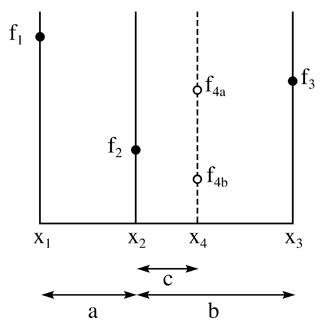

黄金分割搜索图：*x*值的初始三元组为$\left\lbrace x_1 {\textrm{，x}}_2 {\textrm{，x}}_3 \right\rbrace$。

- 如果$f\left(x_4 \right)=f_{4a}$，则选择三元组$\left\lbrace x_1 {\textrm{，x}}_2 {\textrm{，x}}_4 \right\rbrace$。

- 如果$f\left(x_4 \right)=f_{4b}$，则选择三元组$\left\lbrace x_4 {\textrm{，x}}_2 {\textrm{，x}}_3 \right\rbrace$。

#### 为什么是黄金分割率[golden ratio](https://en.wikipedia.org/wiki/Golden_ratio)

我们试图 让每次迭代比率不变：


$$\frac{c}{a}=\frac{a}{b}=\frac{c}{b-c}$$


导致


$${\left(\frac{b}{a}\right)}^2 -\left(\frac{b}{a}\right)=1,\frac{b}{a}=\varphi =\frac{1+\sqrt{5}}{2}=1\ldotp 618033988\ldotp \ldotp \ldotp$$


### [二次插值法](https://en.wikipedia.org/wiki/Successive_parabolic_interpolation)

**Successive parabolic interpolation** is a technique for finding the [extremum](https://en.wikipedia.org/wiki/Extremum) (minimum or maximum) of a continuous [unimodal function](https://en.wikipedia.org/wiki/Unimodal_function) by successively fitting [parabolas](https://en.wikipedia.org/wiki/Parabola) ([polynomials](https://en.wikipedia.org/wiki/Polynomials) of degree two) to a function of one variable at three unique points or, in general, a function of *n* variables at *1+n(n+3)/2* points, and at each iteration replacing the "oldest" point with the extremum of the fitted parabola.

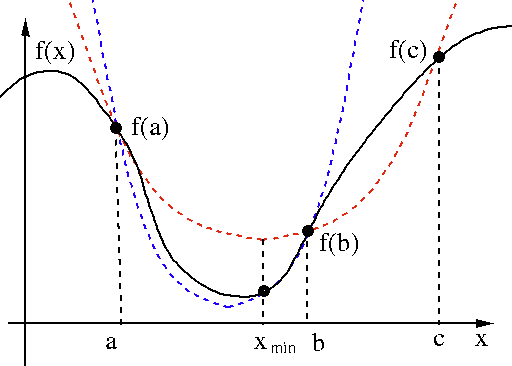

### Matlab 一元函数最小值实战

#### 匿名函数：sin(x) + log(x)

fun = @(x) sin(x)+log(x);
x1 = 0;
x2 = 2*pi;
options = optimset('Display','iter');% 获取迭代过程
[x,fval] = fminbnd(fun,x1,x2,options)

 
 Func-count     x          f(x)         Procedure
    1        2.39996      1.55094        initial
    2        3.88322     0.681175        golden
    3        4.79993      0.57243        golden
    4        4.64589     0.538194        parabolic
    5        4.47428      0.52656        parabolic
    6        4.48863     0.526477        parabolic
    7         4.4876     0.526477        parabolic
    8        4.48767     0.526477        parabolic
    9         4.4877     0.526477        parabolic
   10        4.48764     0.526477        parabolic
 
优化已终止:
 当前的 x 满足使用 1.000000e-04 的 OPTIONS.TolX 的终止条件



x = 4.4877

fval = 0.5265

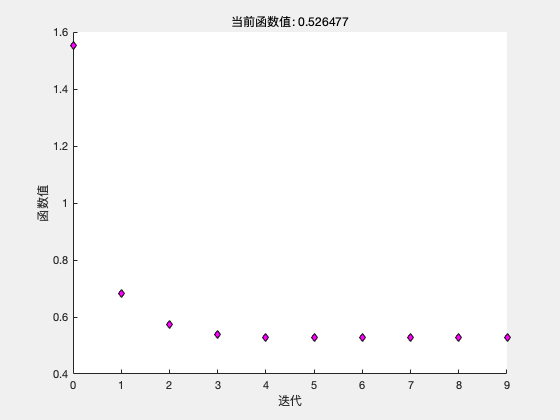

x = 4.4877

fval = 0.5265

exitflag = 1

output = 包含以下字段的 struct :
    iterations: 9
     funcCount: 10
     algorithm: 'golden section search, parabolic interpolation'
       message: '优化已终止:↵ 当前的 x 满足使用 1.000000e-04 的 OPTIONS.TolX 的终止条件↵'


options = optimset('PlotFcns',@optimplotfval);% 获取求解图形
[x,fval,exitflag,output] = fminbnd(fun,x1,x2,options)

#### 文件函数：拟合石墨烯VppP1

 
 Func-count     x          f(x)         Procedure
    1        1.76393     0.605575        initial


    2        2.23607     0.314295        golden


    3        2.52786     0.189482        golden


    4         2.7082     0.150527        golden


    5        2.85888     0.184939        parabolic


    6        2.69848      0.15144        parabolic


    7        2.72671     0.149963        parabolic


    8        2.72423      0.14998        parabolic


    9        2.72775     0.149957        parabolic


   10        2.77784     0.159667        golden


   11        2.74606     0.151645        parabolic


   12        2.73474      0.15028        golden


   13        2.73042     0.150017        golden


   14        2.72877      0.14998        golden


   15        2.72745     0.149958        parabolic


   16        2.72814     0.149966        golden


   17         2.7279      0.14996        golden


   18        2.72764     0.149957        parabolic


   19        2.72772     0.149956        parabolic


   20        2.72769     0.149957        parabolic


 
优化已终止:
 当前的 x 满足使用 1.000000e-04 的 OPTIONS.TolX 的终止条件



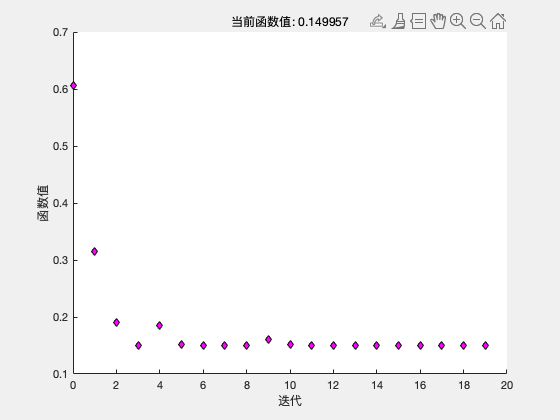

options = optimset('PlotFcns',@optimplotfval,'Display','iter');
x = fminbnd(@Loss_fun_GrapheneTB,1,3,options);

## 多元函数最小值: fminsearch (NM)

`fminsearch` 使用 Lagarias 等人的著作 [[1]](https://ww2.mathworks.cn/help/matlab/math/optimizing-nonlinear-functions.html#bsgpq6q-51) 中所述的 Nelder-Mead 单纯形算法。此算法对 n 维向量 x 使用 n + 1 个点组成的单纯形。此算法首先向 x0 添加各分量 x0(i) 的 5%，以围绕初始估计值 x0 生成一个单纯形。然后，该算法使用上述 n 个向量作为单纯形的除 x0 之外的元素。（如果 x0(i) = 0，则算法使用 0.00025 作为分量 i）。然后，此算法按照以下过程反复修改单纯形。

- *Lagarias, J. C., J. A. Reeds, M. H. Wright, and P. E. Wright. “Convergence Properties of the Nelder-Mead Simplex Method in Low Dimensions.” SIAM Journal of Optimization. Vol. 9, Number 1, 1998, pp. 112–147.*

`fminsearch` 仅对实数求最小值，即向量或数组 x 只能由实数组成，并且 f(x) 必须只返回实数。当 x 具有复数值时，将 x 拆分为实部和虚部。

- 用 x(i) 表示当前单纯形中的点列表 i = 1,...,n + 1。

- 按最小函数值 f(x(1)) 到最大函数值 f(x(n + 1)) 的顺序对单纯形中的点进行排序。在迭代的每个步骤中，此算法都会放弃当前的最差点 x(n + 1) 并接受单纯形中的另一个点。[或者在下面的步骤 7 中，此算法会更改值在 f(x(1)) 上方的所有 n 个点。]

- 生成*反射*点r = 2m – x(n + 1)，**(1)**其中m = Σx(i)/n, i = 1...n，**(2)**并计算 f(r)。

- 如果 f(x(1)) ≤ f(r) < f(x(n))，则接受 r 并终止此迭代。**反射**

- 如果 f(r) < f(x(1))，则计算延伸点 ss = m + 2(m – x(n + 1))，**(3)**并计算 f(s)。

- 如果 f(s) < f(r)，接受 s 并终止迭代。**扩展**

- 否则，接受 r 并终止迭代。**反射**

- 如果 f(r) ≥ f(x(n))，则在 m 和 x(n + 1) 或 r（取目标函数值较低者）之间执行*收缩*。

- 如果 f(r) < f(x(n + 1))（即 r 优于 x(n + 1)），则计算c = m + (r – m)/2**(4)**并计算 f(c)。如果 f(c) < f(r)，则接受 c 并终止迭代。**外收缩**否则，继续执行步骤 7（收缩）。

- 如果 f(r) ≥ f(x(n + 1))，则计算cc = m + (x(n + 1) – m)/2**(5)**并计算 f(cc)。如果 f(cc) < f(x(n + 1))，则接受 cc 并终止迭代。**内收缩**否则，继续执行步骤 7（收缩）。

- 计算 n 点v(i) = x(1) + (x(i) – x(1))/2**(6)**并计算 f(v(i))，i = 2,...,n + 1。下一迭代中的单纯形为 x(1), v(2),...,v(n + 1)。**收缩**

下图显示了 `fminsearch` 可在此过程中计算的点以及每种可能的新单纯形。原始单纯形采用粗体边框。迭代将在符合停止条件之前继续运行。

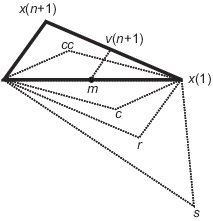

### 多元函数最小值实战

#### 匿名函数：Rosenbrock 函数

在数学[最优化](https://baike.baidu.com/item/%E6%9C%80%E4%BC%98%E5%8C%96)中，**Rosenbrock函数**是一个用来测试最优化[算法](https://baike.baidu.com/item/%E7%AE%97%E6%B3%95)性能的非凸函数，由Howard Harry Rosenbrock在1960年提出 。也称为**Rosenbrock山谷**或**Rosenbrock香蕉函数**，也简称为**香蕉函数**。很难用梯度法求极值。


$$f(x, y)=(1-x)^{2}+100\left(y-x^{2}\right)^{2}$$


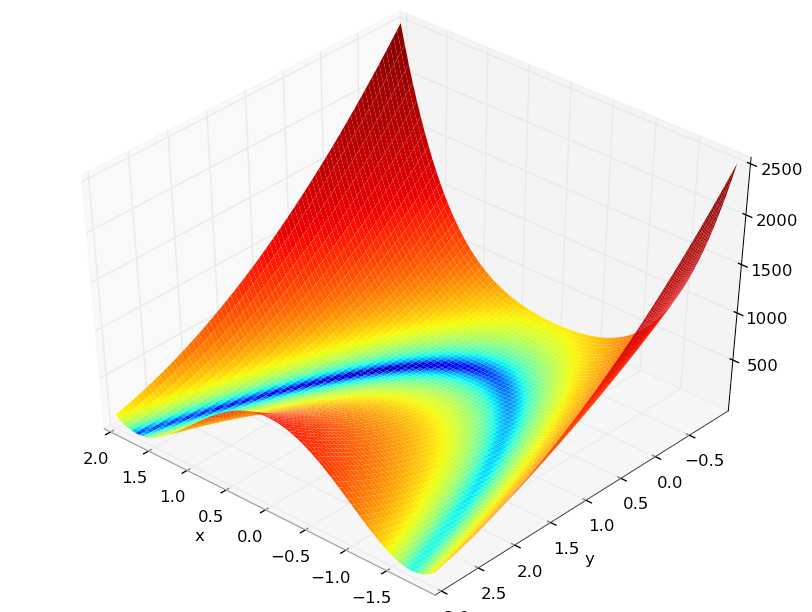

以及其多变量扩展：


$$f(\mathbf{x})=f\left(x_{1}, x_{2}, \ldots, x_{N}\right)=\sum_{i=1}^{N / 2}\left[100\left(x_{2 i-1}^{2}-x_{2 i}\right)^{2}+\left(x_{2 i-1}-1\right)^{2}\right]$$


- *Rosenbrock, H.H. An automatic method for finding the greatest or least value of a function. The Computer Journal. 1960, 3: 175–184.*

 
 Iteration   Func-count     min f(x)         Procedure
     0            1              5.2         


     1            3              5.2         initial simplex


     2            5              5.2         contract inside


     3            7          5.00593         contract inside


     4            9          4.94101         reflect


     5           11          4.94101         contract inside


     6           13          4.88152         reflect


     7           15          4.87794         reflect


     8           17          4.80817         reflect


     9           18          4.80817         reflect


    10           20          4.73424         reflect


    11           22          4.73424         contract inside


    12           24          4.67514         expand


    13           26           4.5252         expand


    14           27           4.5252         reflect


    15           29          4.21963         expand


    16           30          4.21963         reflect


    17           32          3.81047         expand


    18           33          3.81047         reflect


    19           35          3.81047         contract inside


    20           36          3.81047         reflect


    21           38          3.54574         expand


    22           39          3.54574         reflect


    23           41          3.00274         expand


    24           42          3.00274         reflect


    25           44          2.42156         expand


    26           46          2.42156         contract inside


    27           48          1.98052         expand


    28           50          1.98052         contract inside


    29           52          1.98052         contract inside


    30           53          1.98052         reflect


    31           55            1.697         reflect


    32           57            1.697         contract inside


    33           59           1.4573         expand


    34           61           1.4573         contract inside


    35           63          1.34168         expand


    36           64          1.34168         reflect


    37           66          1.11334         reflect


    38           68          1.11334         contract inside


    39           70          1.11334         contract inside


    40           72          1.10212         expand


    41           74         0.967163         expand


    42           76         0.807901         expand


    43           78         0.807901         contract inside


    44           80         0.807901         contract inside


    45           82         0.702333         expand


    46           84         0.558054         expand


    47           86         0.558054         contract inside


    48           88         0.447798         expand


    49           90         0.447798         contract inside


    50           92         0.447798         contract inside


    51           94         0.297861         expand


    52           96         0.166892         expand


    53           98         0.166892         contract inside


    54          100         0.166892         contract inside


    55          101         0.166892         reflect


    56          103         0.106862         reflect


    57          105         0.106862         contract inside


    58          107         0.081208         reflect


    59          109         0.081208         contract inside


    60          111         0.081208         contract inside


    61          113        0.0699633         expand


    62          115        0.0406418         expand


    63          117        0.0198827         expand


    64          119        0.0198827         contract inside


    65          120        0.0198827         reflect


    66          122       0.00647848         reflect


    67          124       0.00647848         contract inside


    68          126       0.00647848         contract inside


    69          128       0.00223583         expand


    70          130       0.00223583         contract inside


    71          132       0.00223583         contract inside


    72          134      0.000583229         reflect


    73          136      0.000510123         reflect


    74          138      0.000112289         contract outside


    75          140      0.000112289         contract inside


    76          142      8.50488e-05         contract inside


    77          144      6.08599e-05         reflect


    78          146        1.384e-05         contract inside


    79          148      9.14308e-06         contract inside


    80          150      7.83972e-06         contract outside


    81          152      8.42613e-07         contract inside


    82          154      8.42613e-07         contract inside


    83          156      7.86142e-07         contract outside


    84          158      2.57848e-07         contract inside


    85          160      1.10265e-07         contract inside


    86          162      1.10265e-07         contract outside


    87          164      5.04112e-08         contract inside


    88          166      3.63513e-08         contract inside


    89          168        9.139e-09         contract inside


    90          170        9.139e-09         contract inside


    91          172      8.53645e-09         reflect


    92          174      9.53935e-10         contract inside


    93          175      9.53935e-10         reflect


    94          177      9.53935e-10         contract inside


    95          179      9.53935e-10         contract outside


    96          181       2.1067e-10         contract inside


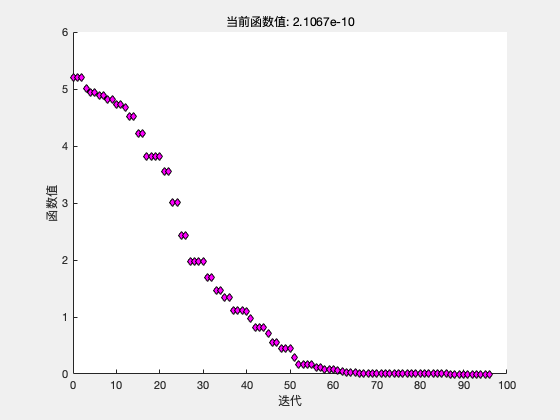

 
优化已终止:
 当前的 x 满足使用 1.000000e-04 的 OPTIONS.TolX 的终止条件，
F(X) 满足使用 1.000000e-04 的 OPTIONS.TolFun 的收敛条件



x =     1.0000    1.0000


fval = 2.1067e-10

exitflag = 1

output = 包含以下字段的 struct :
    iterations: 96
     funcCount: 181
     algorithm: 'Nelder-Mead simplex direct search'
       message: '优化已终止:↵ 当前的 x 满足使用 1.000000e-04 的 OPTIONS.TolX 的终止条件，↵F(X) 满足使用 1.000000e-04 的 OPTIONS.TolFun 的收敛条件↵'


Rosenbrock = @(x)100*(x(2) - x(1)^2)^2 + (1 - x(1))^2;
x0 = [-1.2,1.5];
options = optimset('PlotFcns',@optimplotfval,'Display','iter');
[x,fval,exitflag,output] = fminsearch(Rosenbrock,x0,options)

#### 文件函数：金刚石

拟合金刚石 VppP_0,VppS_0,d_0,fermi